% 清理工作区
clear;
clc;
close all;

%% 1. 定义参数
% 从图四的表格中获取参数值
params = struct();
params.beta1 = 0.01;      % h^-1
params.beta2 = 0.01;      % h^-1
params.KS = 0.52;
params.KH = 0.62;
params.dS = 0.1;        % h^-1
params.dH = 0.3;        % h^-1
params.gamma1 = 1;
params.gamma2 = 1;      % 假设 gamma2 = 1 (非 2xSir2)
params.n1 = 3;
params.n2 = 3;
params.aSt = 0.052;
params.aHt = 0.126;
params.KSt = 0.03;
params.KHt = 0.04;
params.kSt = -0.02;
params.kHt = -0.06;
params.bSt = 1.62;
params.bHt = 2.00;
params.epsilonS = 0.28; % 噪声强度 epsilon_S
params.epsilonH = 0.28; % 噪声强度 epsilon_H

%% 2. 定义 S_total(D) 和 H_total(D) 函数 (根据图二)
dt = 0.1;      % 时间步长
T = 100;        % 模拟总时长 (根据图 E，100小时足够)
num_steps = T / dt;
t_span = 0:dt:T;
fre = 0.37;
D_val = zeros(num_steps,1);
for d = 1:length(D_val)
    if sin(fre*t_span(d)*2*pi) >= 0
        D_val(d) = 2;
    else
        D_val(d) = 0.02;
    end
end


%% 3. 定义带有随机项的常微分方程 (SDEs)
S_total_func = @(D, params) params.aSt * (params.KSt^3 / (params.KSt^3 + D^3)) + params.kSt * D + params.bSt;
H_total_func = @(D, params) params.aHt * (params.KHt^3 / (params.KHt^3 + D^3)) + params.kHt * D + params.bHt;
sdes_func = @(t, x, params, S_total_D, H_total_D) [
    (params.beta1 + x(1)^params.n1 / (params.KS^params.n1 + x(1)^params.n1)) * (S_total_D - x(1)) - (params.dS + params.gamma1 * x(2)) * x(1);
    (params.beta2 + x(2)^params.n2 / (params.KH^params.n2 + x(2)^params.n2)) * (H_total_D - x(2)) - (params.dH + params.gamma2 * x(1)) * x(2)
];
diffusion_coeffs = [params.epsilonS; params.epsilonH];

%% 4. 模拟多条 SDE 轨迹并分类
% 设置模拟参数
dt = 0.1;      % 时间步长
T = 100;        % 模拟总时长 (根据图 E，100小时足够)
num_steps = T / dt;
t_span = 0:dt:T;

num_trajectories = 200; % 模拟的轨迹数量，可以调整以获得更多数据
S0 = 0.5; H0 = 0.8; % 初始条件
initial_conditions = repmat([S0; H0], 1, num_trajectories); % 所有轨迹从相同初始条件开始

% 存储所有轨迹，为了方便分类和绘图
all_S_trajectories = zeros(num_steps + 1, num_trajectories);  
all_H_trajectories = zeros(num_steps + 1, num_trajectories);
all_F_trajectories = zeros(num_steps + 1, num_trajectories);
hit_time = zeros(1, num_trajectories);

% Mode 1 对应 HAP (S) 高，Sir2 (H) 低
% Mode 2 对应 HAP (S) 低，Sir2 (H) 高
threshold_S = 0.05; 
threshold_H = 0.1; 

fprintf('正在模拟 %d 条 SDE 轨迹...\n', num_trajectories);

正在模拟 200 条 SDE 轨迹...


tic; % 计时开始

for traj_idx = 1:num_trajectories
    X = initial_conditions(:, traj_idx); % 获取当前轨迹的初始条件
    Y = 0;
    
    %存储当前轨迹的数据
    current_S_traj = zeros(num_steps + 1, 1);
    current_H_traj = zeros(num_steps + 1, 1);
    current_F_traj = zeros(num_steps + 1, 1);
    current_S_traj(1) = X(1);
    current_H_traj(1) = X(2);
    current_F_traj(1) = Y;
    flagF = false;

    for i = 1:num_steps
        S_total_D = S_total_func(D_val(i), params);
        H_total_D = H_total_func(D_val(i), params);

        dW = dt* randn(3, 1); % Wiener 过程增量 (两个独立的噪声项)
        drift_val = sdes_func(t_span(i), X, params, S_total_D, H_total_D);
        
        % Extract drift components
        dF_drift = damage_ode(Y,X(1),X(2),t_span(i));
        dS_drift = drift_val(1);
        dH_drift = drift_val(2);
        noise_S_term = 0.3 * X(1) .* dW(1); % epsilonS * S * dW_S
        noise_H_term = 0.3 * X(2) .* dW(2); % epsilonH * H * dW_H
        noise_F_term = 0.3 * Y .* dW(3);
        % Apply update
        X(1) = X(1) + dS_drift * dt + noise_S_term;
        X(2) = X(2) + dH_drift * dt + noise_H_term;
        Y = Y + dF_drift *dt + noise_F_term;

        % 确保 S 和 H 不会变成负值
        X(1) = max(0, X(1));
        X(2) = max(0, X(2));
        Y = max(0, Y);
        current_S_traj(i+1) = X(1);
        current_H_traj(i+1) = X(2);
        current_F_traj(i+1) = Y;
        if Y >= 5 && flagF == false
            hit_time(traj_idx) = i;
            flagF = true;
        end 
     
    if flagF == false
        hit_time(traj_idx) = inf;
    end


    end
    all_S_trajectories(:, traj_idx) = current_S_traj;
    all_H_trajectories(:, traj_idx) = current_H_traj;
    all_F_trajectories(:, traj_idx) = current_F_traj;
end
sim_time = toc; % 计时结束
fprintf('SDE 模拟完成，耗时: %.4f 秒\n', sim_time);

SDE 模拟完成，耗时: 0.9085 秒


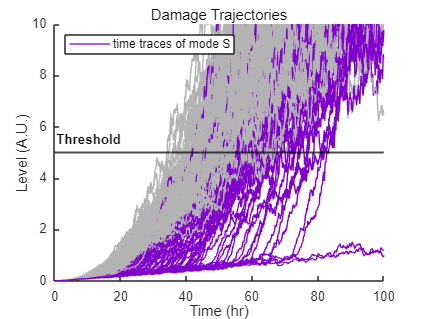


%% 5. 分类并绘制轨迹 (类似图 E)
% 创建图形窗口
figure;

% Sir2 (H) 轨迹图 (左列)
subplot(1, 2, 1); % 1行2列的第一个图
hold on; % 允许在同一轴上绘制多条线
title('Sir2'); 
xlabel('Time (hr)');
ylabel('Level (A.U.)');
% ylim([0 2]); % 可以根据您的数据范围设置Y轴限制

% HAP (S) 轨迹图 (右列)
subplot(1, 2, 2); % 1行2列的第二个图
hold on;
title('HAP');
xlabel('Time (hr)');
ylabel('Level (A.U.)');
% ylim([0 2]); % 可以根据您的数据范围设置Y轴限制
    
figure;
hold on; % 允许在同一轴上绘制多条线
title('Damage Trajectories'); 
xlabel('Time (hr)');
ylabel('Level (A.U.)');
damage_threshold = 5; 
% 绘制 threshold 直线
yline(damage_threshold, 'k', 'LineWidth', 1.5, 'DisplayName', 'Damage Threshold'); 

ylim([0 10]);
% 在图上标注 threshold
% 可以选择在直线的末尾、中间或者其他合适位置进行标注
text_x_position = t_span(end) * 0.2; % 将标注放在X轴的80%位置
text_y_position = damage_threshold + 0.20; % 将标注放在阈值线上方一点
text(text_x_position, text_y_position, 'Threshold', 'Color', 'black', ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'bottom', ...
    'FontSize', 10, 'FontWeight', 'bold');
% 遍历所有轨迹并根据终点分类绘制
num_mode1 = 0;
num_mode2 = 0;
num_modeS = 0;
damage_color = [0.7, 0.7, 0.7];
for traj_idx = 1:num_trajectories
    final_S = all_S_trajectories(end, traj_idx);% 获取 S 的最终值
    first_mode1_time = find(all_S_trajectories(:,traj_idx) < threshold_S);
    final_H = all_H_trajectories(end, traj_idx); % 获取 H 的最终值
    first_mode2_time = find(all_H_trajectories(:,traj_idx) < threshold_H);
    final_F = all_F_trajectories(end, traj_idx);
% 根据最终 S 值判断模式
    if final_S < threshold_S % S 值低对应 Mode 1
        if first_mode1_time > 188
            plot_color = [0.5, 0, 0.8]; % 紫色
            mode_label = 'Mode S';
            num_modeS = num_modeS + 1;
            damage_color = [0.5, 0, 0.8];
        else
            plot_color = [0.996, 0.627, 0.831]; % 红色
            mode_label = 'Mode 1';
            num_mode1 = num_mode1 + 1;
            damage_color = [0.7, 0.7, 0.7];
        end

    elseif final_H < threshold_H % H 值低对应 Mode 2
        if first_mode2_time > 200
            plot_color = [0.5, 0, 0.8]; % 紫色
            mode_label = 'Mode S';
            num_modeS = num_modeS + 1;
            damage_color = [0.5, 0, 0.8];
        else
            plot_color = [0.0, 0.0, 0.8]; % 蓝色
            mode_label = 'Mode 2';
            num_mode2 = num_mode2 + 1;
            damage_color = [0.7, 0.7, 0.7];
        end
    else
        plot_color = [0.5, 0, 0.8]; % 紫色
        mode_label = 'Mode S';
        num_modeS = num_modeS + 1;
        damage_color = [0.5, 0, 0.8];
    end
    
    figure(1); % 切换到第一个图窗
    subplot(1, 2, 1);
    plot(t_span, all_S_trajectories(:, traj_idx), 'Color', plot_color, 'LineWidth', 0.5);

   % 绘制 HAP (S) 轨迹 - 在第一个图窗的右子图
    figure(1); % 切换到第一个图窗
    subplot(1, 2, 2);
    plot(t_span, all_H_trajectories(:, traj_idx), 'Color', plot_color, 'LineWidth', 0.5);

    % 绘制 damage 轨迹
    figure(2); % 切换到第二个图窗
    plot(t_span, all_F_trajectories(:, traj_idx), 'Color', damage_color, 'LineWidth', 0.5);
end
figure(2);
h6 = plot(NaN, NaN, 'Color', [0.5, 0, 0.8], 'LineWidth', 1, 'DisplayName', 'time traces of mode S');
legend(h6, 'Location', 'Northwest'); 
exportgraphics(gcf, 'damage_traj_osc.pdf', 'ContentType', 'vector');


% 添加图例 (只添加一次)
fig = figure(1); % 切换回第一个图窗
set(fig, 'Position', [100, 100, 1200, 500]);
ax1 = subplot(1, 2, 1);
set(ax1, 'Position', [0.08, 0.15, 0.40, 0.7]);
h1 = plot(ax1, NaN, NaN, 'Color', [0.996, 0.627, 0.831], 'LineWidth', 1,'DisplayName', 'mode 1'); % 占位符用于图例
h2 = plot(ax1, NaN, NaN, 'Color', [0.0, 0.0, 0.8], 'LineWidth', 1, 'DisplayName', 'mode 2'); % 占位符用于图例
h3 = plot(NaN, NaN, 'Color', [0.5, 0, 0.8], 'LineWidth', 1, 'DisplayName', 'mode S'); 
legend(ax1, [h1, h2, h3], 'Location', 'NorthEast');
hold on;

ax2 = subplot(1, 2, 2);
set(ax2, 'Position', [0.52, 0.15, 0.40, 0.7]);
h3 = plot(ax2, NaN, NaN, 'Color', [0.996, 0.627, 0.831], 'LineWidth', 1, 'DisplayName', 'mode 1'); % 占位符用于图例
h4 = plot(ax2, NaN, NaN, 'Color', [0.0, 0.0, 0.8], 'LineWidth', 1, 'DisplayName', 'mode 2'); % 占位符用于图例
h5 = plot(NaN, NaN, 'Color', [0.5, 0, 0.8], 'LineWidth', 1, 'DisplayName', 'mode S');
legend(ax2, [h3, h4, h5], 'Location', 'NorthEast'); % 可以调整位置

fprintf('\n模拟完成。Mode 1 轨迹数量: %d, Mode 2 轨迹数量: %d, Mode S 轨迹数量: %d\n', num_mode1, num_mode2, num_modeS);


模拟完成。Mode 1 轨迹数量: 103, Mode 2 轨迹数量: 16, Mode S 轨迹数量: 81


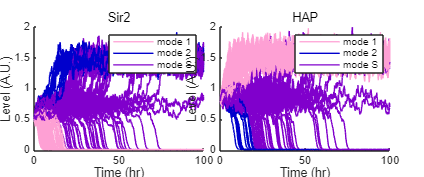

exportgraphics(gcf, 'stochastic_traj_osc.pdf', 'ContentType', 'vector');


%绘制二维概率密度图
figure;clf;
title('2D Probability Map for Glucose Oscillations');
xlabel('Sir2 (AU)');
ylabel('HAP (AU)');
xlim([0 2]);
ylim([0 2]);
hold on;
num_colors = 256;
color_points = [
    1, 1, 1;
    0.5, 0, 0.8;
    0, 0, 1;
    0, 1, 0;
    1, 1, 0;
    1, 0, 0;
];
N_points = size(color_points, 1);
interpolation_points = linspace(0, 1, N_points);
R_interp = interp1(interpolation_points, color_points(:, 1), linspace(0, 1, num_colors));
G_interp = interp1(interpolation_points, color_points(:, 2), linspace(0, 1, num_colors));
B_interp = interp1(interpolation_points, color_points(:, 3), linspace(0, 1, num_colors));
custom_color_map = [R_interp(:), G_interp(:), B_interp(:)];
[P_osc, S_centers_osc, H_centers_osc] = Calculate_Probability_Density(all_S_trajectories, all_H_trajectories, [0 2], [0 2], 200);
imagesc(S_centers_osc, H_centers_osc, P_osc);
set(gca, 'YDir', 'normal');
colormap(custom_color_map);
clim([0 prctile(P_osc(:), 99.5)]);
disp(max(P_osc(:)))

   1.0401e+03



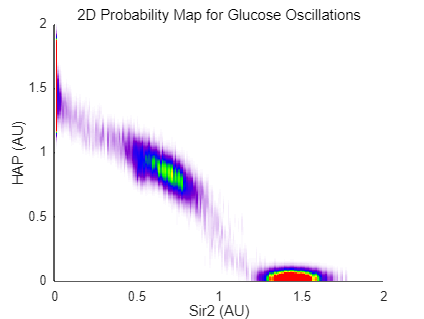

exportgraphics(gcf, '2D_probability_map_osc.pdf', 'ContentType', 'vector');